%页码：P134
%作者；暴富
%时间：2024-08-2
%项目：本地信息观测器和邻域信息控制器

clc
clear
lineStyles = linspecer(6); % 指定线型颜色,一页有几条线

%%系统初始化
A = [0,1,0;0,0,1;-0.2,0.2,1.1];
B = [0;0;1];
C = [0,0,1];

G = diag([30,0,0,0,30]);
E = [0 1 1 1 0;...
    1 0 1 1 0;...
    1 1 0 0 1;...
    0 0 1 0 1;...
    0 1 0 1 0];
D = diag(sum(E,2));
L = D -E;
varGamma  = (eye(5)+D+G)\(L+G);

%特征值位置
eig_varGamma = eig(varGamma);
c0_SVFB = (max(real(eig_varGamma))+min(real(eig_varGamma)))/2;
r0_SVFB = max(abs(eig_varGamma - c0_SVFB));

%Riccati设计的稳定区域
%%可控可观的判断
Rc = ctrb(A,B);
rank(Rc); %ans = 3结果可控
Ro = obsv(A,C);
rank(Ro); %ans = 3结果可观

%%LQR
Q1 = 0.1*eye(3); %想要收敛快点就增大对角值
Q2 = 0.1*eye(3);
R = 1e-5;%希望控制输入的影响较小
[K,P1] = dlqr(A,B,Q1,R) ;
[F,P2] = dlqr(A',C',Q2,R);
F = F';
%定义矩阵M和N
M = inv(sqrtm(Q1'))*A'*P1*B*inv(B'*P1*B)*B'*P1*A*inv(sqrtm(Q1));
N = inv(sqrtm(Q2'))*A*P2*C'*inv(C*P2*C')*C*P2*A'*inv(sqrtm(Q2));

%同步区域的半径
r_SVFB = max(svd(M))^(-1/2);
r_OBS = max(svd(N))^(-1/2);

%观测器和控制器设计的c都一样
c = 1/c0_SVFB;

%验证位似变换是否落在稳定区域

abs(c*eig_varGamma-1)<r_SVFB;
(r0_SVFB/c0_SVFB)<r_SVFB %等于1则满足条件

ans = logical
   1



%验证位似变换是否落在稳定区域
abs(c*eig_varGamma-1)<r_OBS;
(r0_SVFB/c0_SVFB)<r_OBS %等于1则满足条件

ans = logical
   1


%%仿真初始化
N = 20;
t = 1:N;

%%agent初始化,6个agent，一个agent3个状态，每一页对应状态迭代
X_Real = zeros(3,5,N);
X_obv = zeros(3,5,N);
X0_Real = zeros(3,1,N);
X0_obv = zeros(3,1,N);

%跟踪误差
tracking_error = zeros(3,5,N);
%观测器误差
observe_error = zeros(3,5,N);


%设置随机状态
X_Real_initial = randn(3,5);
X_Real(:,:,1) = X_Real_initial;

X_obv_initial = randn(3,5);
X_obv(:,:,1) = X_obv_initial;

X0_Real_initial = randn(3,1);
X0_Real(:,:,1) = X0_Real_initial;
%领导者观测器的初始值，leader 可以知道自己的状态
X0_obv(:,:,1) =  X0_Real(:,:,1);

## **原始系统**

### **1.跟随者**


$$x_i\left(k+1\right)=Ax_i\left(k\right)-BK\hat{x}_i(k)$$


$\hat{x}_i(k+1)=A \hat{x}_i(k)-BK\hat{x}_i(k)-c_1(1+d_i+g_i)^{-1}F \Bigg( \sum_{j}e_{ij}(\tilde{y}_{j}(k)-\tilde{y}_{i}(k))+g_{i}(y_{0}(k)-\tilde{y}_{i}(k))  \Bigg)$观测器

### 2.领导者：


$$$$
x_0(k+1)\,\,=\,\,Ax_0(k)
$$
$$



$$y_0(k) = Cx_0(k)$$


### 定义


$$$$
sum\_ystate=\sum_{j\in N_i}{e_{ij}}(\tilde{y}_j(k)-\tilde{y}_i(k))=\sum_{j\in N_i}{e_{ij}}*C*\Bigg([x_j(k)-\hat{x}_j(k)]-[x_i(k)-\hat{x}_i(k)]\Bigg)
$$
$$



$$G\_term2=g_i*C\Bigg(x_0(k)-(x_i(k)-\hat{x}_i(k))\Bigg)$$


### 整理的

**1.跟随者**


$$x_i\left(k+1\right)=Ax_i\left(k\right)-BK\hat{x}_i(k)$$


$\hat{x}_i(k+1)=A \hat{x}_i(k)-BK\hat{x}_i(k)-c_1(1+d_i+g_i)^{-1}F \Bigg( sum\_ystate +  G\_term2  \Bigg)$观测器

### 2.领导者：


$$$$
x_0(k+1)\,\,=\,\,Ax_0(k)
$$
$$



$$y_0(k) = Cx_0(k)$$


for k = 2:N
    X0_Real(:,1,k) = A*X0_Real(:,1,k-1);
    X0_obv(:,1,k) = X0_Real(:,1,k); % leader 可以知道自己的状态
    for i = 1:5
        sum_ystate = 0;
        G_term2 = G(i,i)*C*(X0_Real(:,1,k-1)-(X_Real(:,i,k-1)-X_obv(:,i,k-1)));
        for j = 1:5
             sum_ystate = sum_ystate + E(i,j)*C*((X_Real(:,j,k-1)-X_obv(:,j,k-1))-(X_Real(:,i,k-1)-X_obv(:,i,k-1)));
        end
        X_Real(:,i,k) = A*X_Real(:,i,k-1) - B*K*X_obv(:,i,k-1);
        X_obv(:,i,k) = A*X_obv(:,i,k-1) - B*K*X_obv(:,i,k-1) - c*(1+D(i,i)+G(i,i))^(-1)*F*(sum_ystate + G_term2);
    end
    %%误差
    tracking_error(:,:,k-1) = X_Real(:,:,k-1) - X0_Real(:,:,k-1);
    observe_error(:,:,k-1) = X_Real(:,:,k-1) - X0_obv(:,:,k-1);
end

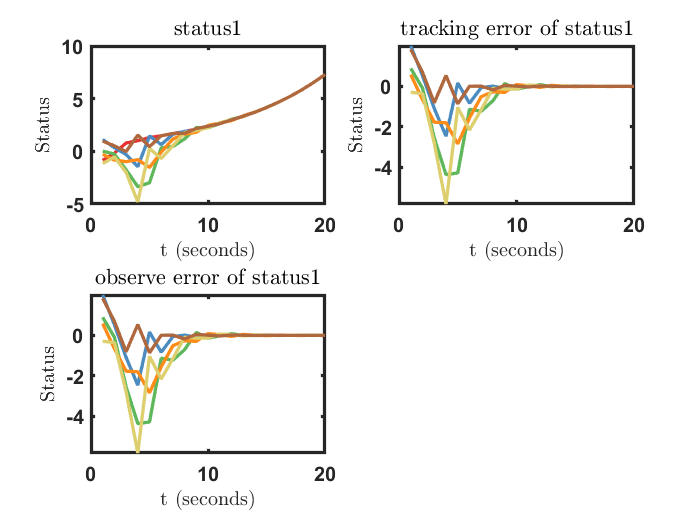

%%绘图:状态对应一直即可，x_1对x_1,x_2对x_2，x_2对x_2，x_2对x_2
%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）
xlim([0.0 25.0])
ylim([-3 3])

subplot(2,2,1)

plot(t,reshape(X0_Real(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','status1')

subplot(2,2,2)
%跟踪误差

plot(t,reshape(tracking_error(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(tracking_error(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(tracking_error(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(tracking_error(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(tracking_error(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','tracking error of status1')
 

subplot(2,2,3)
%观测器误差

plot(t,reshape(observe_error(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(observe_error(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(observe_error(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(observe_error(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(observe_error(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','observe error of status1')




%%作图思路：本系统是观测器估计状态，利用估计状态，进行闭环设置，故我们只绘实际图像即可，不要绘制观测器


